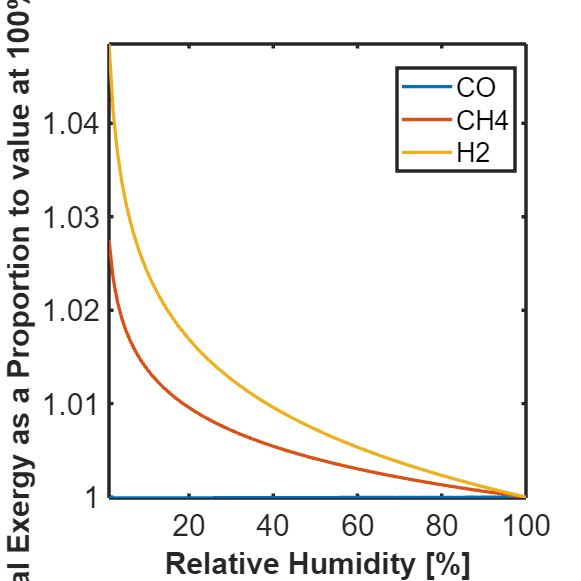

T0 = 298.15;
P0 = oneatm;
dead = GRI30;  
X0 = 'N2:0.757223,O2:0.202157,Ar:0.009015,CO2:0.000397,H2O:0.031208';
set(dead, "T", T0, "P", P0, 'X', X0)
X00 = 'N2:0.757223,O2:0.202157,Ar:0.009015,CO2:0.000397,H2O:';



% rh = 0.01:0.01:1;
% n = size(rh,2);
% X_c = zeros(n,3);
% % CO, CH4, H2
% g = GRI30;
% 
% set(g, "T", T0, "P", P0, "X", 'CO:1')
% for i = 1:n
%     P_h2o = rh2P(rh(i), T0);
%     X_h2o = P_h2o/P0;
%     set(dead, 'X', [X00,char(string(X_h2o))])
%     [x_tm, x_c] = exergy_calc(g, dead);
%     X_c(i,1) = x_c;
% end
% 
% set(g, "T", T0, "P", P0, "X", 'CH4:1')
% for i = 1:n
%     P_h2o = rh2P(rh(i), T0);
%     X_h2o = P_h2o/P0;
%     set(dead, 'X', [X00,char(string(X_h2o))])
%     [x_tm, x_c] = exergy_calc(g, dead);
%     X_c(i,2) = x_c;
% end
% 
% set(g, "T", T0, "P", P0, "X", 'H2:1')
% for i = 1:n
%     P_h2o = rh2P(rh(i), T0);
%     X_h2o = P_h2o/P0;
%     set(dead, 'X', [X00,char(string(X_h2o))])
%     [x_tm, x_c] = exergy_calc(g, dead);
%     X_c(i,3) = x_c;
% end

% Normalize
for i = 1:3
    X_c(:,i) = X_c(:,i)./X_c(n,i);
end

plot(rh*100, X_c)
legend(["CO", "CH4", "H2"])
xlabel("Relative Humidity [%]")
ylabel("Chemical Exergy as a Proportion to value at 100% Humidity")
improvePlot

function P_h2o = rh2P(rh, T)
    w = Water; set(w, "T", T);
    setState_satVapor(w);
    P_h2o = rh*pressure(w);
end
function [X_tm, X_c] = exergy_calc(gas, dead)
    % Dead State
    T0 = 25+273.15;
    P0 = oneatm;
    R = 8.314; % universal gas constant
    tm_eq = GRI30; 
    set(tm_eq, "T", T0, "P", P0, "X", moleFractions(gas));
    
    % Thermo-Mechanical Exergy
    X_tm = (intEnergy_mass(gas)-intEnergy_mass(tm_eq)) + P0*(1/density(gas) - 1/density(tm_eq)) - T0*(entropy_mass(gas)-entropy_mass(tm_eq)); % J/kg
    mu = chemPotentials(dead);

    % Decomposing Input to Environmental 
    % [ C, H, N, O, Ar]
    mm_all = molecularWeights(gas);
    mm = [mm_all(speciesIndex(gas,'C')), mm_all(speciesIndex(gas,'H')), mm_all(speciesIndex(gas,'N')), mm_all(speciesIndex(gas,'O')), mm_all(speciesIndex(gas,'Ar'))]; % molar masses (g/mol)
    mass_frac = [ elementalMassFraction(gas,'C'),  elementalMassFraction(gas,'H'),  elementalMassFraction(gas,'N'), elementalMassFraction(gas,'O'),  elementalMassFraction(gas,'Ar')];
    mole_frac = (mass_frac./mm)./(sum(mass_frac./mm)); % normalize to 1mol of elements
    avg_atoms = meanMolecularWeight(gas)/sum(mm.*mole_frac); % average atoms per molecule
    comb_frac = mole_frac*avg_atoms; % atoms of each element from combusting a mole of input gas

    % Assign Inputs and Outputs
    n_out_co2 = comb_frac(1);
    n_out_h20 = comb_frac(2)/2;
    n_in_o2 = max(n_out_h20/2 + n_out_co2 - (comb_frac(4)/2), 0);
    n_out_o2 = max((comb_frac(4)/2) - n_out_h20/2 - n_out_co2 , 0);
    n_in_n2 = 3.76*n_in_o2;
    n_out_n2 = n_in_n2 + comb_frac(3)/2;
    n_in_ar = n_in_o2*(0.009015/0.202157);
    n_out_ar = n_in_ar + comb_frac(5);
    
    % Sum Chemical Potentials
    mu_in = n_in_o2*(mu(speciesIndex(dead, 'O2')) + R*T0*log(moleFraction(dead,'O2'))) ... 
        + n_in_n2*(mu(speciesIndex(gas, 'N2')) + R*T0*log(moleFraction(dead,'N2'))) ...
        + n_in_ar*(mu(speciesIndex(gas, 'Ar')) + + R*T0*log(moleFraction(dead,'Ar')));
    mu_out = n_out_co2*(mu(speciesIndex(dead, 'CO2')) + R*T0*log(moleFraction(dead,'CO2'))) ...
        + n_out_h20*(mu(speciesIndex(gas, 'H2O')) + R*T0*log(moleFraction(dead,'H2O'))) ...
        + n_out_n2*(mu(speciesIndex(gas,'N2')) + R*T0*log(moleFraction(dead,'N2'))) ...
        + n_out_ar*(mu(speciesIndex(gas, 'Ar')) + R*T0*log(moleFraction(dead,'Ar'))) ...
        + n_out_o2*(mu(speciesIndex(gas, 'O2')) + R*T0*log(moleFraction(dead,'O2')));
    % These chem potentials are [J/kmol of gas in]
    X_c = gibbs_mass(tm_eq) - (mu_out - mu_in)/meanMolecularWeight(gas); % J/Kg
end

function X = exergy(gas, dead)
    [X_tm, X_c] = exergy_calc(gas, dead);
    X = X_tm + X_c;
end

function X = exergy_flow(gas, dead)
    P_in = pressure(gas);
    P0 = oneatm;
    X_in = exergy(gas, dead);
    X_ex = ((1/density(gas))*(P_in - P0)); % [J/kg]
    % Ignoring potential and kinetic energy
    X = X_in + X_ex;
end
